# Module 2: Action Functional Gradient Descent (AFGD) algorithm

clear all
close all

## Load model

lattice_edge = 2; 
model_name = 'Schlogl_1_'+string(lattice_edge)

model_name = "Schlogl_1_2"

plotnam = "2-Schlogl"

plotnam = "2-Schlogl"

model_name = "Selkov"

model_name = "Selkov"

plotnam = "Selkov"

plotnam = "Selkov model"

model_name = "SYN3_FINAL"
plotnam = "12-D Syntrophy model"

model_name = "Cluster_3_catalyst"
plotnam = "3-D Cluster model with catalysis"

model_name = "Cluster_3_catalyst_w_temp"
plotnam = "3-D Cluster model with catalysis & templating"

#### Load ..._Ham.mat from 'data' folder

load('..\Data\'+model_name+'_Ham.mat')

#### Load heteroclinic network

i = row in hc_net. j = column in hc_net - 1 

load('..\Data\' + model_name + '_hcnet.mat')
pos_root_arr

$$pos\_root\_arr = \left(\begin{array}{cc} 1 & 1\\ 2 & 2\\ 2.1654 & 1.0930\\ 1.0930 & 2.1654\\ 2.8367 & 1.1633\\ 1.1633 & 2.8367\\ 3 & 3\\ 2.9070 & 1.8346\\ 1.8346 & 2.9070 \end{array}\right)$$

hc_net

hc_net =      3     5     1
     4     6     1
     8     7     5
     9     7     6


i = 1; j = 1;
sad_pt = i; stab_pt_choice = j;

i = 1; j = 2;
sad_pt = i; stab_pt_choice = j;

#### Load initial condition

Straight 

load('..\Data\' + model_name + '_initcond_'+string(i)...
        +'_'+string(j)+'straight.mat')

Spiral

load('..\Data\' + model_name + '_initcond_'+string(i)...
+'_'+string(j)+'spiral.mat')

#### Sample space uniform and plot

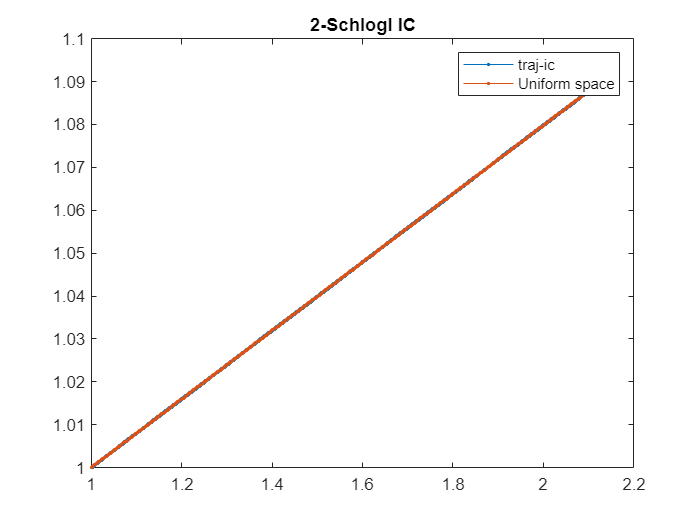

%Space uniform sampling
traj_pts = 500;
traj_ic = double(traj_ic);
[traj,len_curve_prime] = space_uniform_sampling(traj_ic,traj_pts);
%Plot
figure()
plot(traj_ic(:,1),traj_ic(:,2:end),'.-')
hold on
plot(traj(:,1),traj(:,2:end),'.-')
hold off
legend('traj-ic','Uniform space')
title(plotnam + ' IC')

#### Load from existing data

save('traj_n_s_2000_Schlogl.mat',"traj_n_s")

load('traj_n_s_2000_Schlogl.mat')
traj = traj_n_s; traj_pts = size(traj,1);
[traj,len_curve_prime] = space_uniform_sampling(traj,traj_pts);

load("..\Data\Schlogl_1_2_descend_1_2straight_500_10-Jul-2022.mat")
iter

iter = 100

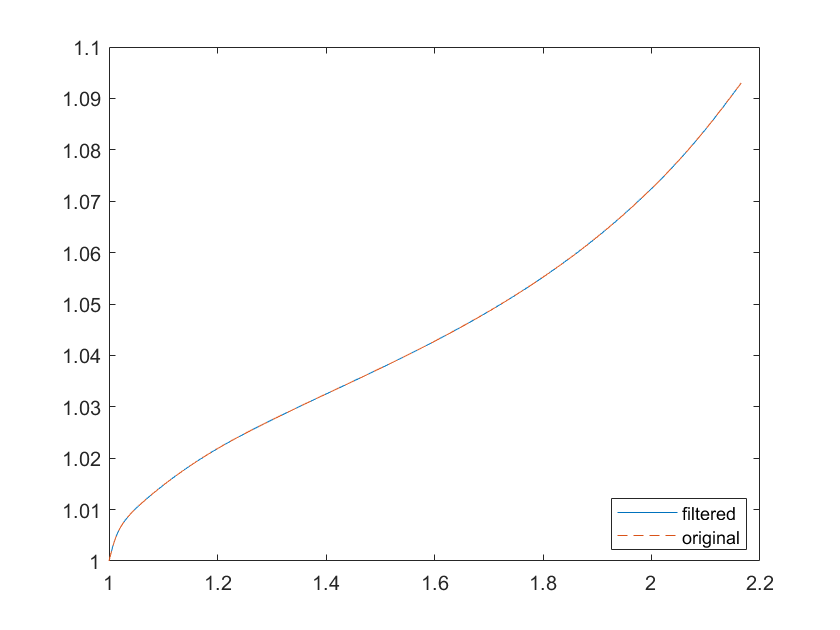

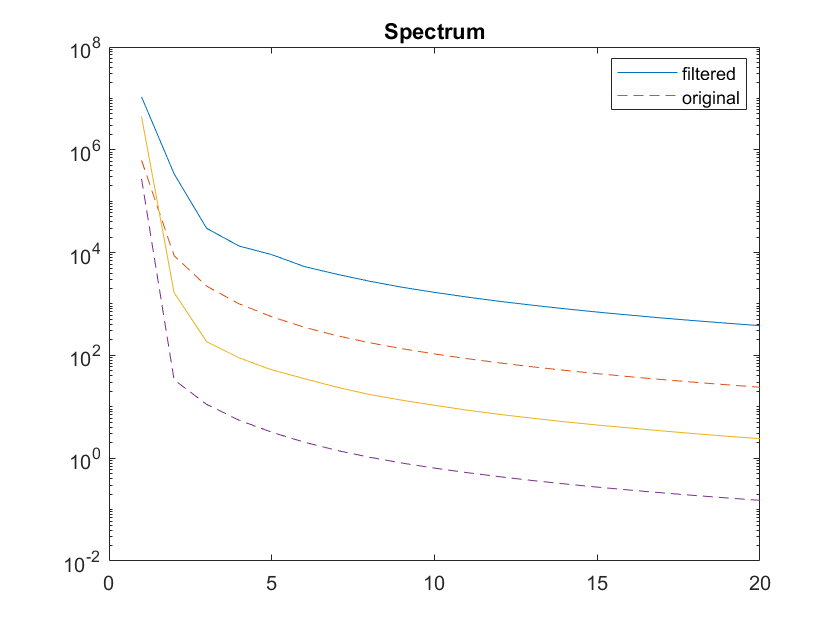

iter = 45;
PS_traj  = picker_arr_idx(PS_arr,traj_pt_arr,iter);
t_traj = picker_arr_idx(time_arr,traj_pt_arr,iter);
traj = time_uniform_filter(PS_traj(:,1:num_spec),t_traj,2000,40);

[traj,len_curve_prime] = space_uniform_sampling(traj,2000);

[PS_traj, t_traj, delta_x] = traj_2_PS_traj_func(traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,num_smooth);    
plot_PS_traj(PS_traj,t_traj,plotnam,save_plot_name,0);
%delta_x_s = picker_arr_idx(deltax_lp_arr,traj_pt_arr,20);
delta_x_s =  smooth_traj_butter(delta_x,5); 
debugging_deltax_plots(delta_x,delta_x_s,f0,plotnam,save_plot_name,0);

## Initialize Descender

%number of points in trajectory
traj_pts = size(traj,1);

%Initialize arrays for saving and delta_x_s
Initialize_descender

S_arr =    0.016810810232826



%Save data to file in the data folder
savenam = '..\Data\' + model_name + '_descend_'+string(sad_pt)...
+'_'+string(stab_pt_choice)+'straight_'+string(traj_pts)+'_'+string(date)+'.mat'

savenam = "..\Data\Schlogl_1_2_descend_1_2straight_500_10-Mar-2023.mat"

%Save data to file in the data folder (for spiral)
%savenam = '..\Data\' + model_name + '_descend_'+string(sad_pt)...
%+'_'+string(stab_pt_choice)+'spiral_'+string(traj_pts)+'_'+string(date)+'.mat'

save_plot_name_root = 'Plots/'+model_name+'_'+string(sad_pt)...
        +'_'+string(stab_pt_choice)+'_'+string(traj_pts)+'_'+string(date)

save_plot_name_root = "Plots/Schlogl_1_2_1_1_500_10-Mar-2023"

%Plot PS_traj and save
save_plot_name = 'Plots/'+model_name+'_'+string(sad_pt)...
+'_'+string(stab_pt_choice)+'_PS_traj_IC.png'

save_plot_name = "Plots/Schlogl_1_2_1_1_PS_traj_IC.png"

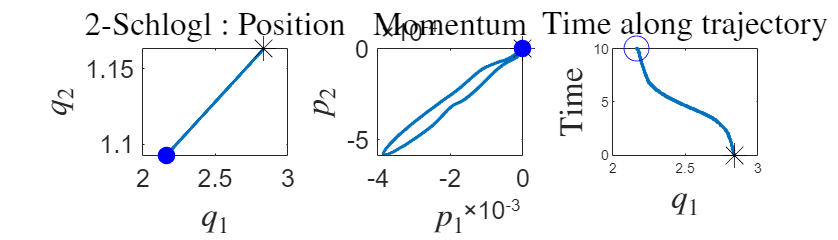

plot_PS_traj(PS_traj,t_traj,plotnam,save_plot_name,0);

delta_x_s =  smooth_traj_butter(delta_x,f0); 

%Plot delta_x and save
save_plot_name = 'Plots/'+model_name+'_'+string(sad_pt)...
+'_'+string(stab_pt_choice)+'_deltax_IC.png'

save_plot_name = "Plots/Schlogl_1_2_1_2_deltax_IC.png"

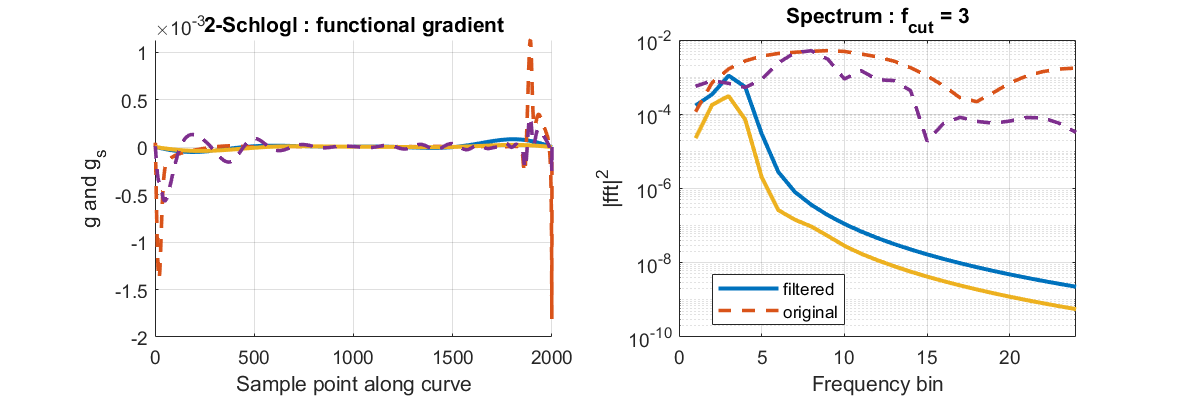

debugging_deltax_plots(delta_x,delta_x_s,f0,plotnam,save_plot_name,0);

## Actual descent

%Actual descender
eps_ic = 1; eps = eps_ic; eps_min = 0.01;     %Initial and least step size
delta_S = 10; err_thresh = 10^(-1); 
f0_max = 40; f0_step = 0.1; 
eps_S_thresh = 10^(-7); delta_S_thresh = 10^(-7);
iter_max = 10; iter = 1;

f0 =5;

format long
anneal_ct = 0;
while f0<f0_max  &&  iter<iter_max
    iter = iter + 1;
    traj_pts = size(traj,1);

    %take a step in the gradient by picking appropriate step size
    [eps, action_S_new, PS_traj, t_traj, delta_x, S_traj] = eps_picker...
        (traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,delta_x_s,action_S,eps,num_smooth,eps_min,delta_S_thresh);
    traj = PS_traj(:,1:num_spec);
    delta_S = action_S_new - action_S;
    [iter, eps, action_S_new, delta_S, f0]
    eps_used = eps;
    %if delta_S is positive, then break. If less than threshold then
    %increase cutoff frequency. If descent has stopped, anneal.
    %{
    if delta_S > 0
        disp('Why is action increasing? Error!')
        break
    
    elseif eps == 0
        anneal_ct = anneal_ct + 1;
        f0 = f0 - 0.1; eps = 0.5; delta_S = 1; traj_pts_new = traj_pts;
        if anneal_ct >2
            disp('Annealing')
            traj_pts_new = traj_pts+1000;
            f0 = f0; eps = 1; delta_S = 1;  traj_pts = traj_pts_new;
            anneal_ct = 0;
        end
        traj = time_uniform_filter(traj,t_traj,traj_pts_new,35);
        [PS_traj, t_traj, delta_x] = traj_2_PS_traj_func(traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,num_smooth);    
        %}
    if f0 > 6
        f0 = f0; eps = 0.5; delta_S = 1; traj_pts_new = traj_pts;
        traj_pts_new = traj_pts+1000;
        traj = time_uniform_filter(traj,t_traj,traj_pts_new,35);
        [traj,len_curve_prime] = space_uniform_sampling(traj,traj_pts);
        [PS_traj, t_traj, delta_x] = traj_2_PS_traj_func(traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,num_smooth);    

    elseif abs(delta_S)<delta_S_thresh || eps < eps_min
        f0 = f0 + 0.1; eps = 1; delta_S = 1;  
        traj = time_uniform_filter(traj,t_traj,traj_pts,35);
        [traj,len_curve_prime] = space_uniform_sampling(traj,traj_pts);
        [PS_traj, t_traj, delta_x] = traj_2_PS_traj_func(traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,num_smooth);    
    end

    
    %smoothen gradient for next iteration
    delta_x_s =  smooth_traj_butter(delta_x,f0); 

    
    %Update descender and save to file
    Update_descender
    save(savenam)
    
    %Plot some stuff in every some iterations
    if mod(iter,5)==0
        save_plot_name = 'Plots/'+model_name+'_'+string(sad_pt)...
        +'_'+string(stab_pt_choice)+'_deltax_'+string(iter)+'.png'
        plot_PS_traj(PS_traj,t_traj,plotnam,save_plot_name,0);
        debugging_deltax_plots(delta_x,delta_x_s,f0,plotnam,save_plot_name,0);
    end

    
end

delta_S =     -4.322523632801362e-06


ans =    3.000000000000000   1.000000000000000   0.016806487709193  -0.000004322523633   5.000000000000000


Unrecognized function or variable 'a_min'.

Error in Update_descender (line 16)
a_arr = [a_arr; a_min];

format short

save_plot_name

save_plot_name = "Plots/Schlogl_1_2_1_2_deltax_35.png"

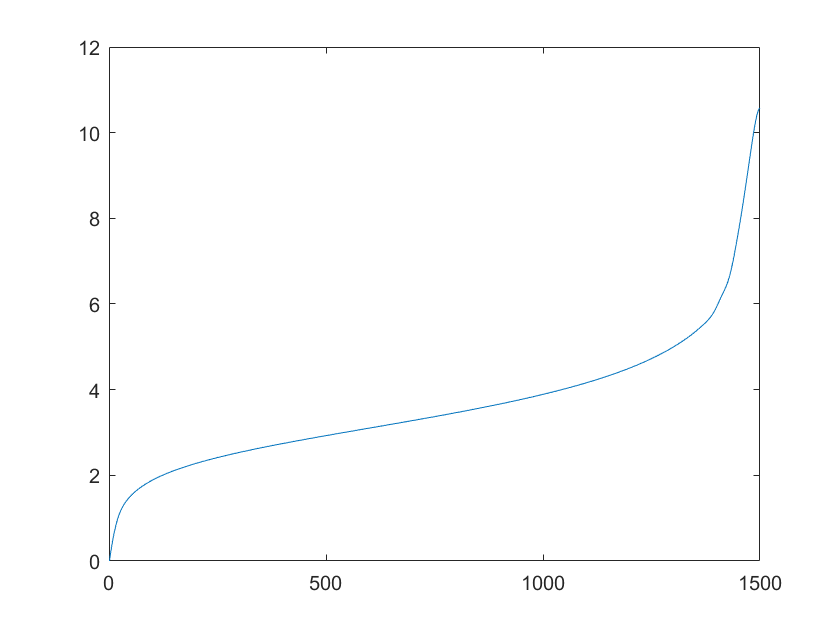

iter = 30;
traj_pts = 500;
PS_traj  = picker_arr_idx(PS_arr,traj_pt_arr,iter);
t_traj = picker_arr_idx(time_arr,traj_pt_arr,iter);
figure()
plot(t_traj)

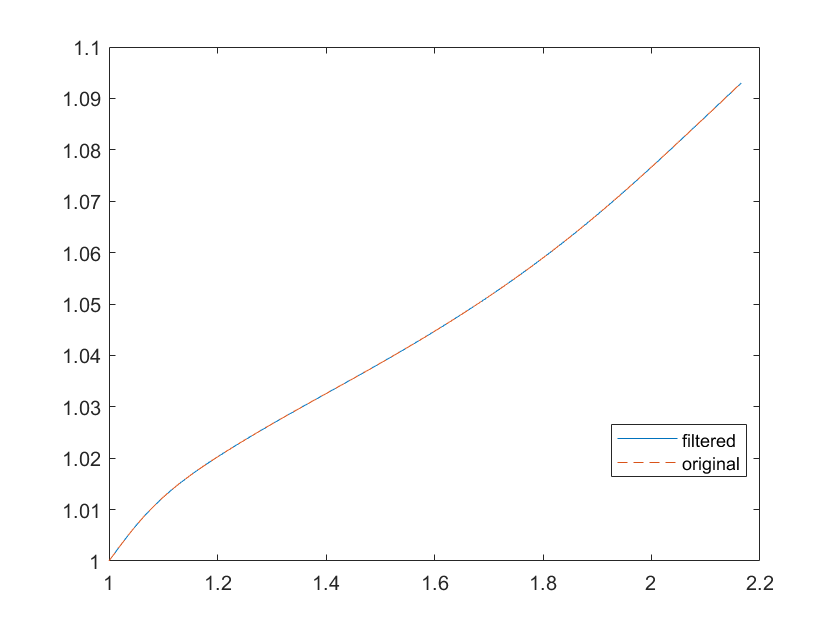

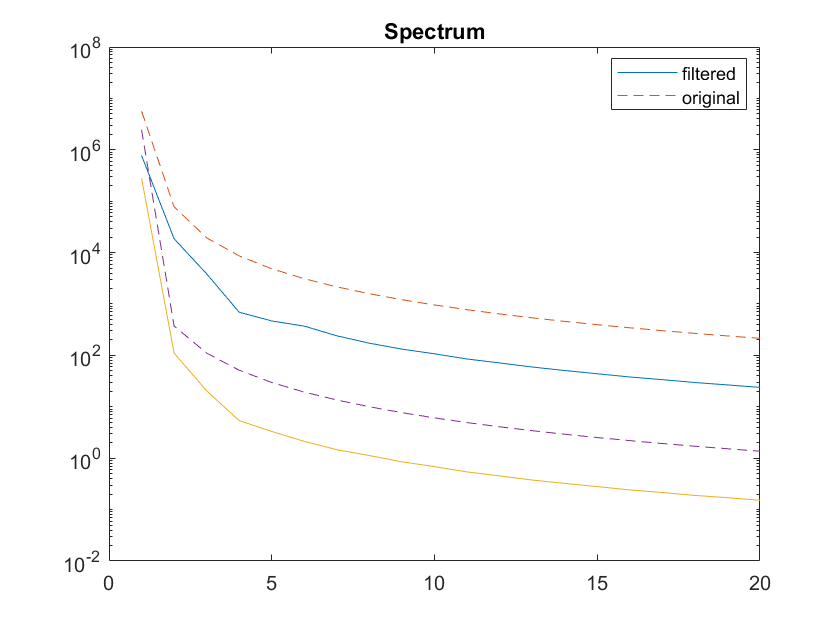

traj = PS_traj(:,1:2);
traj = time_uniform_filter(traj,t_traj,traj_pts,40);

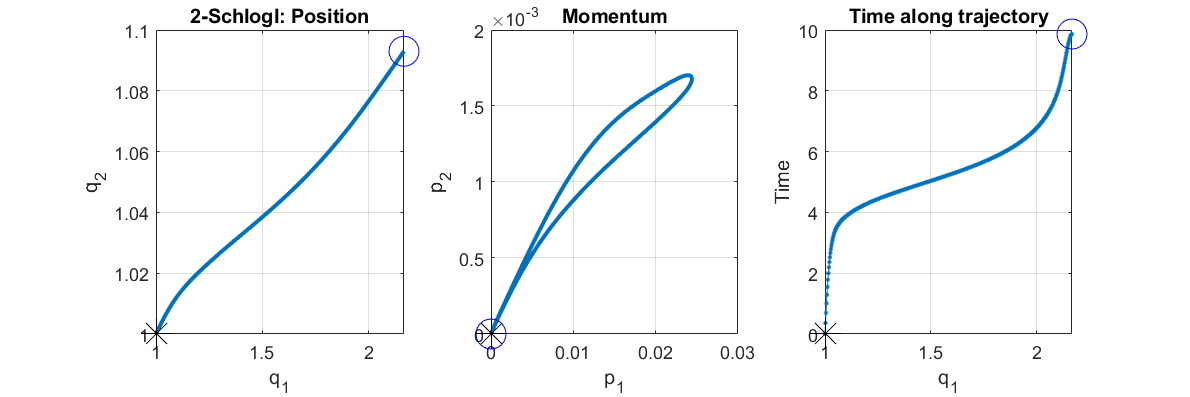

[traj,len_curve_prime] = space_uniform_sampling(traj,traj_pts);
[PS_traj, t_traj, delta_x] = traj_2_PS_traj_func(traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,num_smooth);    
plot_PS_traj(PS_traj,t_traj,plotnam,save_plot_name,0);

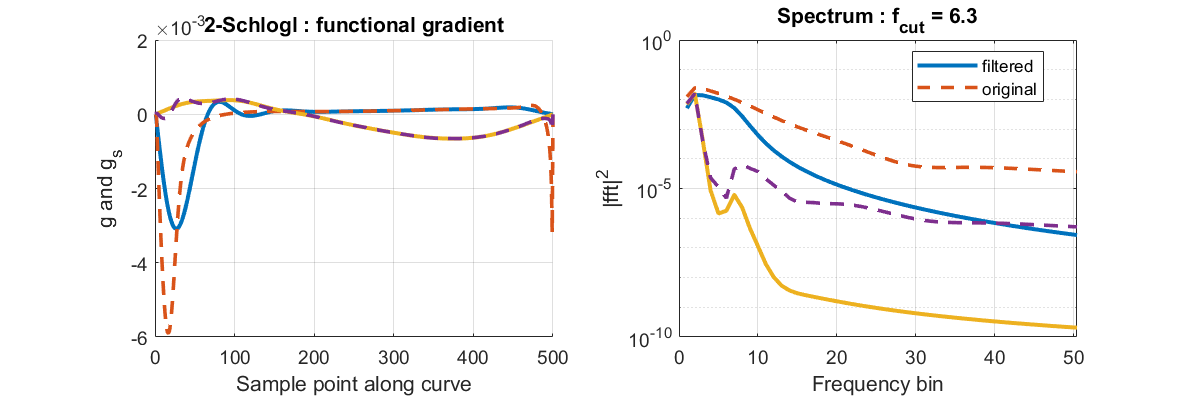

%delta_x_s = picker_arr_idx(deltax_lp_arr,traj_pt_arr,20);
delta_x_s =  smooth_traj_butter(delta_x,f0); 
debugging_deltax_plots(delta_x,delta_x_s,f0,plotnam,save_plot_name,0);

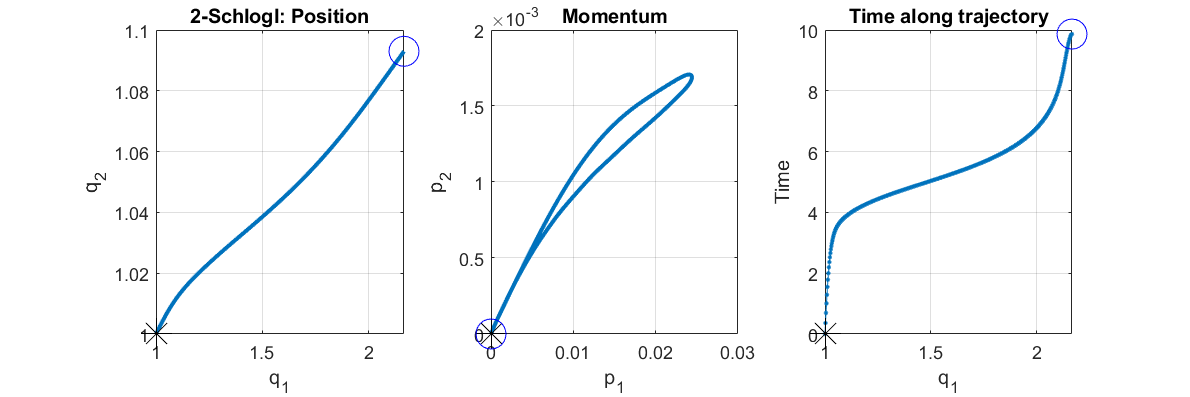

plot_PS_traj(PS_traj,t_traj,plotnam,save_plot_name,0);

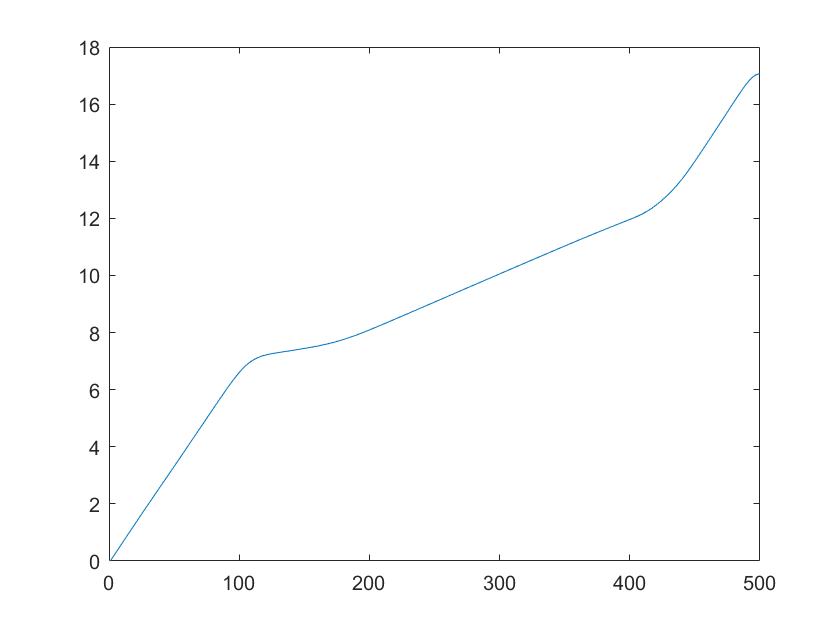

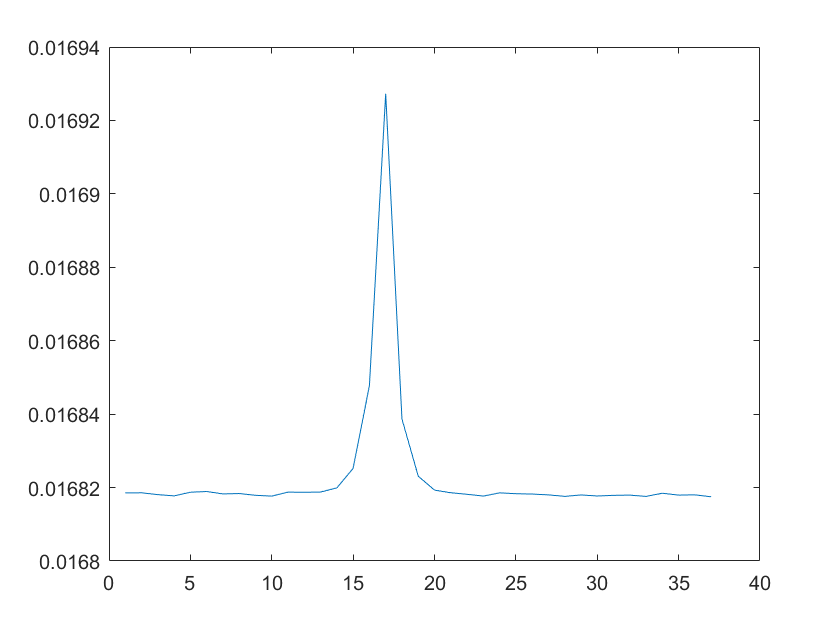

figure()
plot(t_traj)

#### Look for a settiing which works

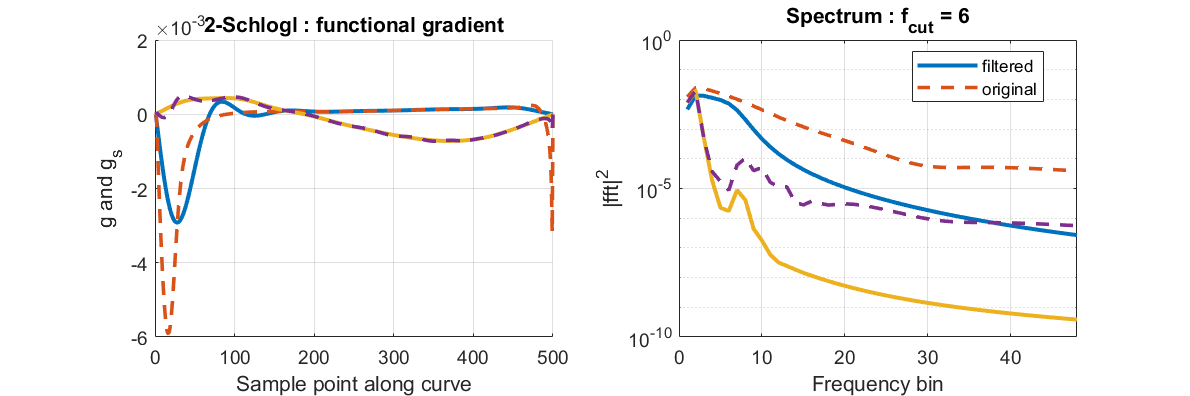

format long
f0 = 6; eps_min = 0.001;eps = 0.5;
delta_x_s =  smooth_traj_butter(delta_x,f0); 
debugging_deltax_plots(delta_x,delta_x_s,f0,plotnam,save_plot_name,0);

[eps, action_S_new, PS_traj, t_traj, delta_x, S_traj] = eps_picker...
    (traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,delta_x_s,action_S,eps,num_smooth,eps_min);

delta_S =      7.119623560098709e-04


delta_S = action_S_new - action_S;
[iter, eps, action_S_new, delta_S, f0]

ans =   26.000000000000000   0.500000000000000   0.016800152640389   0.000711962356010   6.000000000000000


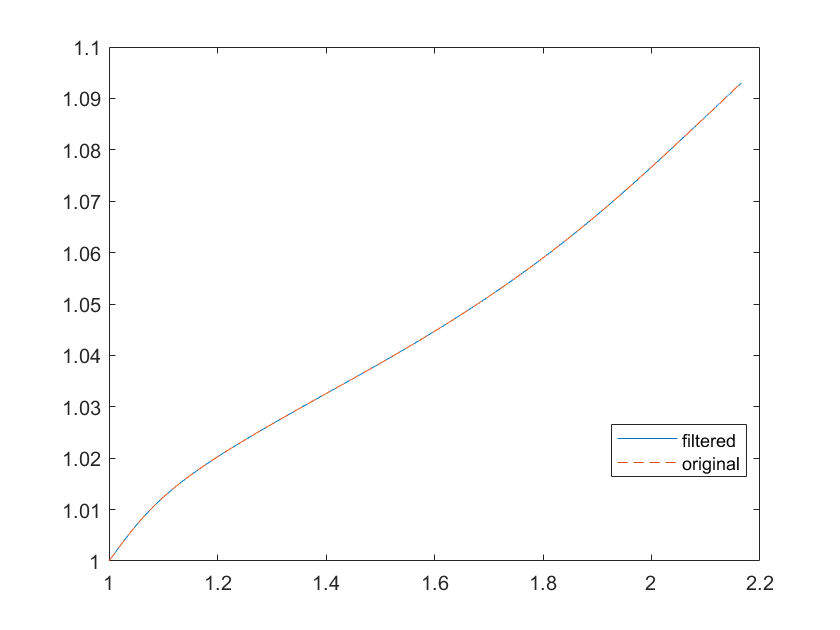

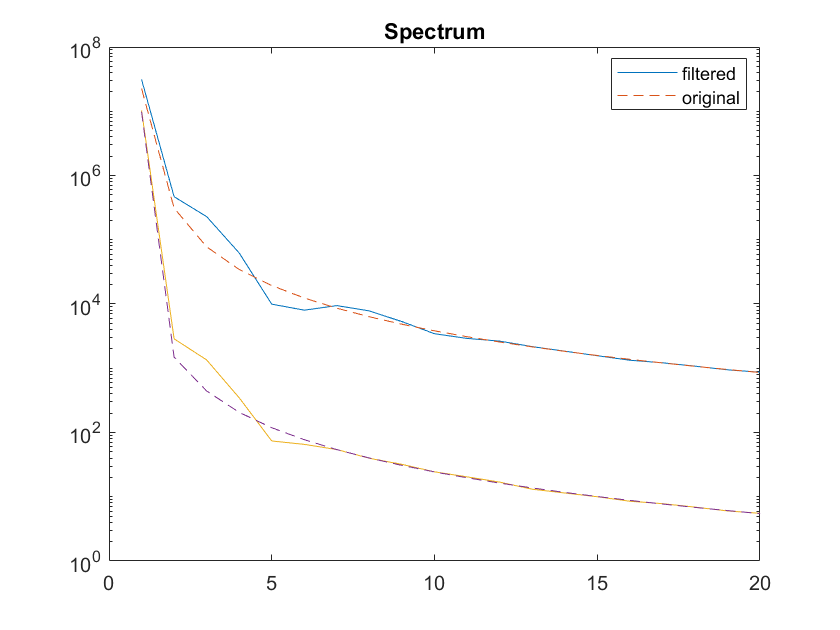

traj_pts_new = 3000;
traj = time_uniform_filter(traj,t_traj,traj_pts_new,35);

%[traj,len_curve_prime] = space_uniform_sampling(traj_n_s,traj_pts_new);
[PS_traj, t_traj, delta_x] = traj_2_PS_traj_func(traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,num_smooth);    

f0 = 6; eps_min = 0.03;eps = 0.1;
delta_x_s =  smooth_traj_butter(delta_x,f0); 
[eps, action_S_new, PS_traj, t_traj, delta_x, S_traj] = eps_picker...
    (traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,delta_x_s,action_S,eps,num_smooth,eps_min);
delta_S = action_S_new - action_S;
[iter, eps, action_S_new, delta_S, f0]

ans =   20.000000000000000                   0   0.016088190284380                   0   6.000000000000000


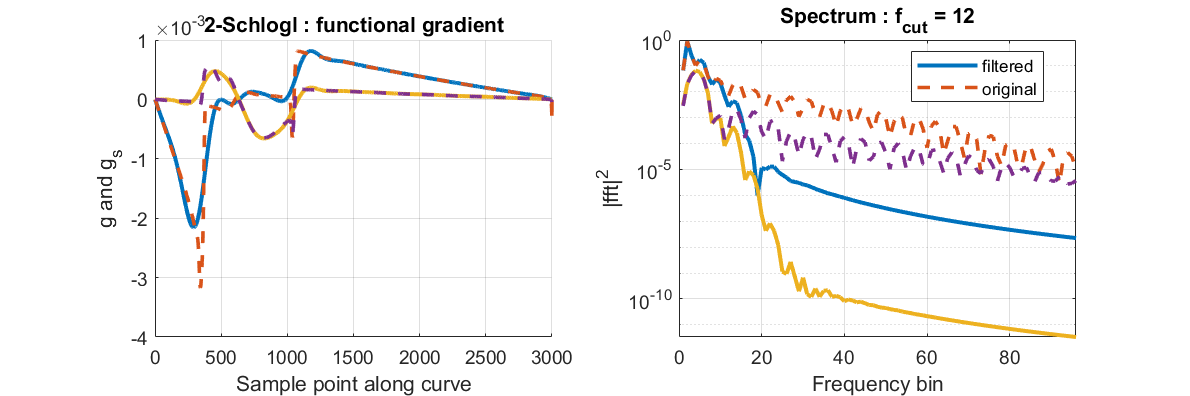

debugging_deltax_plots(delta_x,delta_x_s,f0,plotnam,save_plot_name,0);

save_plot_name = "Plots/Schlogl_1_2_1_2_2000_11-Jul-2022_35_HamEoM_1711.png"

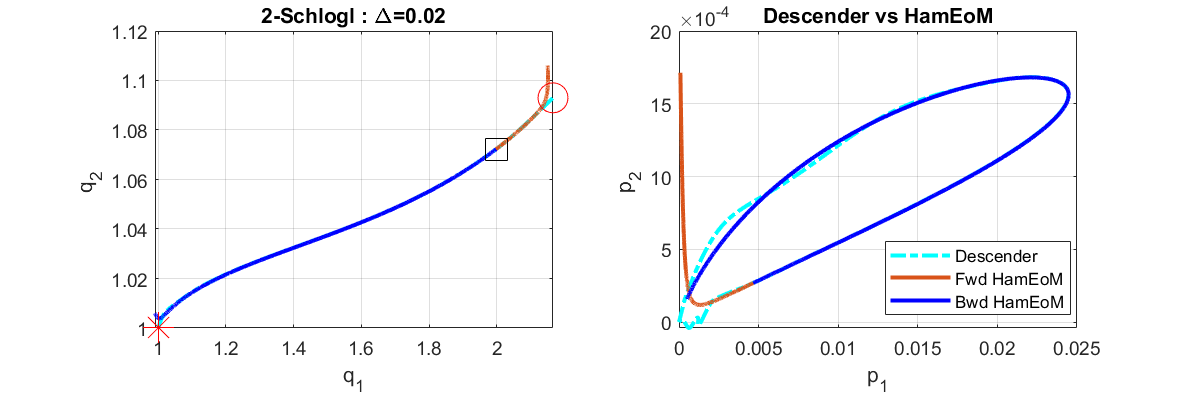

a =    0.020095655946439


iter = 35;
PS_traj  = picker_arr_idx(PS_arr,traj_pt_arr,iter);
S_traj = picker_arr_idx(S_traj_arr,traj_pt_arr,iter);
t_traj = picker_arr_idx(time_arr,traj_pt_arr,iter);
save_plot_name = save_plot_name_root + '_' + string(iter) + '_HamEoM';
a = Ham_closest_approach(PS_traj,S_traj,t_traj,dHamdp_fun, dHamdq_fun,save_plot_name,1,plotnam)

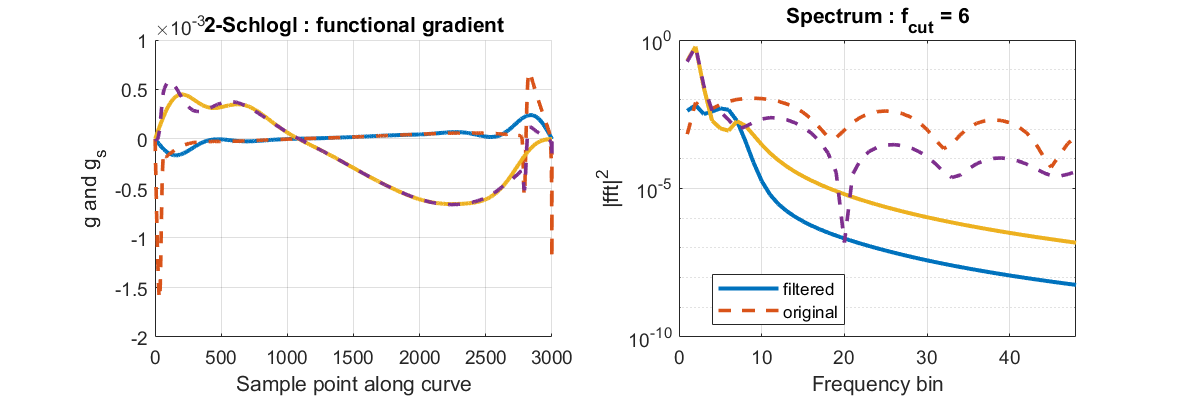

debugging_deltax_plots(delta_x,delta_x_s,f0,plotnam,save_plot_name,0);

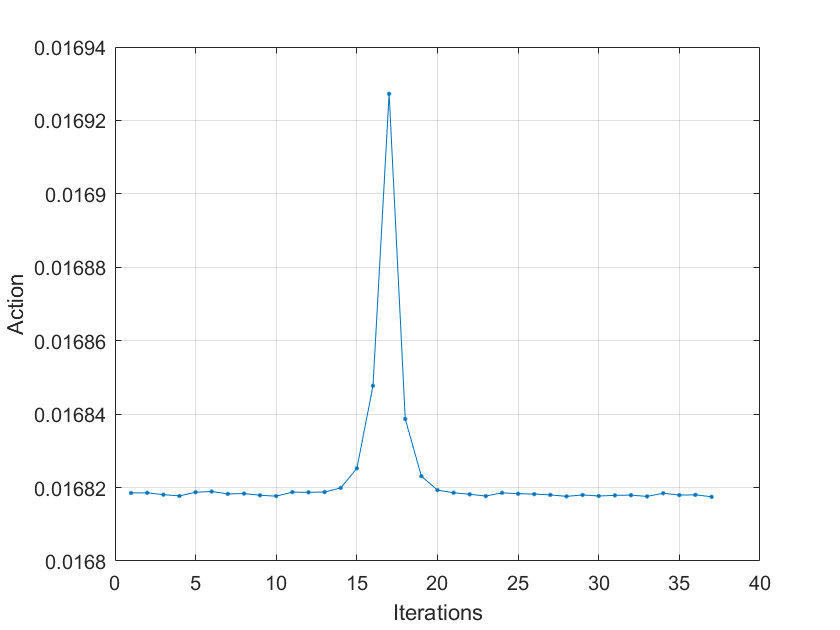

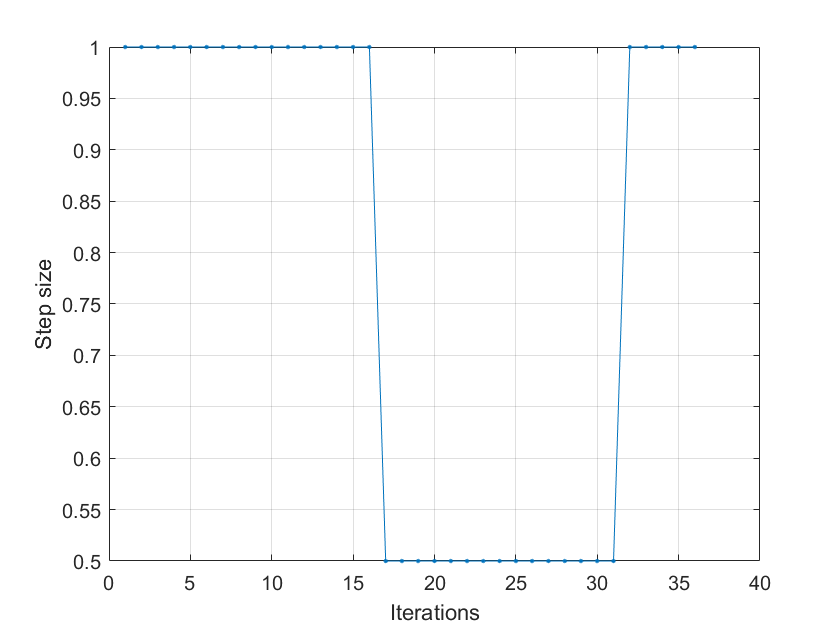

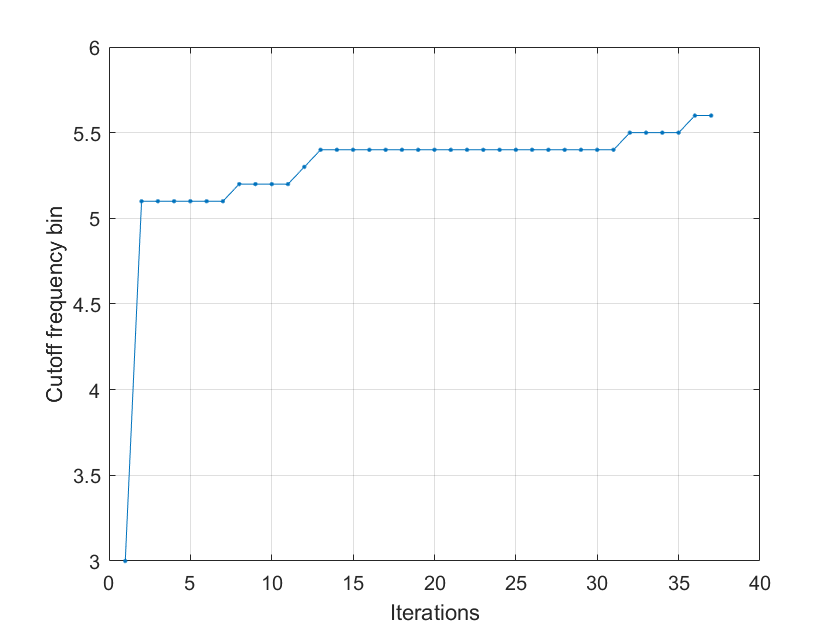

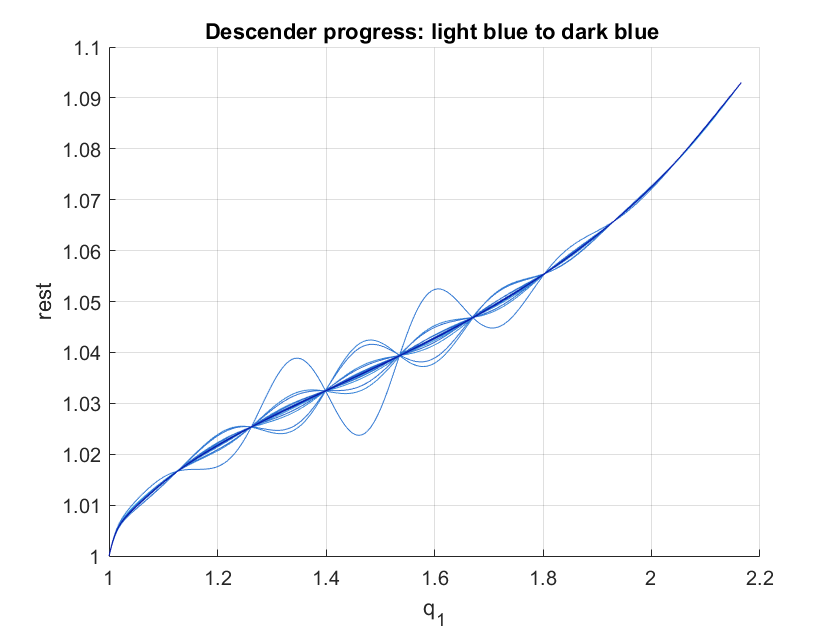

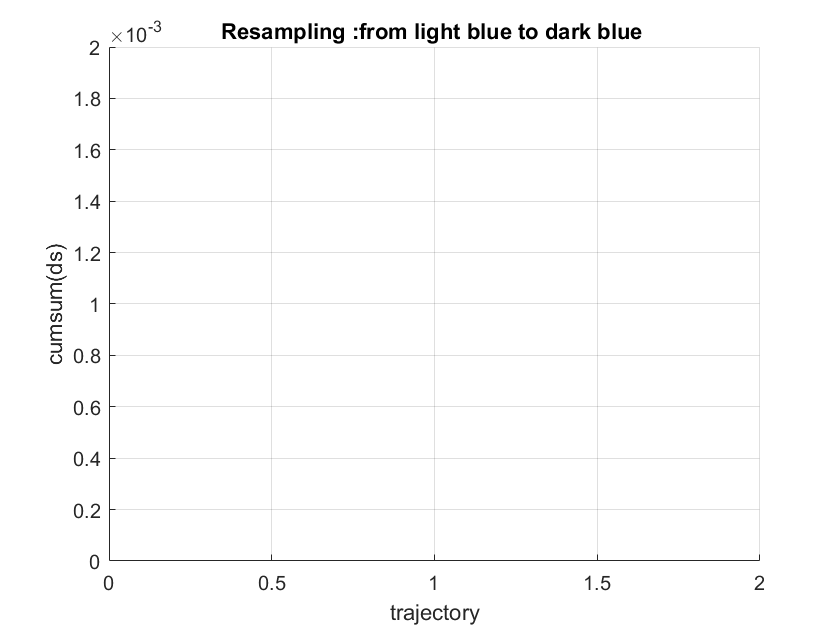

Index in position 2 exceeds array bounds (must not exceed 1).

Error in plot_everything_1 (line 65)
surf(s_resamp_arr(:,1:dtraj:traj_pts))

plot_everything_1

f0 = 5; delta_x_s =  smooth_traj_butter(delta_x,f0); 

choose_iter = iter-1; f0 = 2;
PS_traj  = picker_arr_idx(PS_arr,traj_pt_arr,choose_iter);
delta_x_s = picker_arr_idx(deltax_lp_arr,traj_pt_arr,choose_iter);


iter_max = 24;f0 = 0.5;eps = 0.0001;

iter_max = 57;f0 = 2;

traj_n_s = time_uniform_filter(traj,t_traj,traj_pts_new,100);
[PS_traj, t_traj, delta_x] = traj_2_PS_traj_func(traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,num_smooth);    
figure()
plot(PS_traj(:,3),PS_traj(:,4))

traj_n_s = time_uniform_filter(traj,t_traj,traj_pts_new,45);
[PS_traj, t_traj, delta_x] = traj_2_PS_traj_func(traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,num_smooth);    
figure()
plot(PS_traj(:,3),PS_traj(:,4))

figure()
semilogy(abs(fft(traj_n_s)).^2)
hold on
semilogy(abs(fft(traj)).^2,'--')
hold off
xlim([0 20])

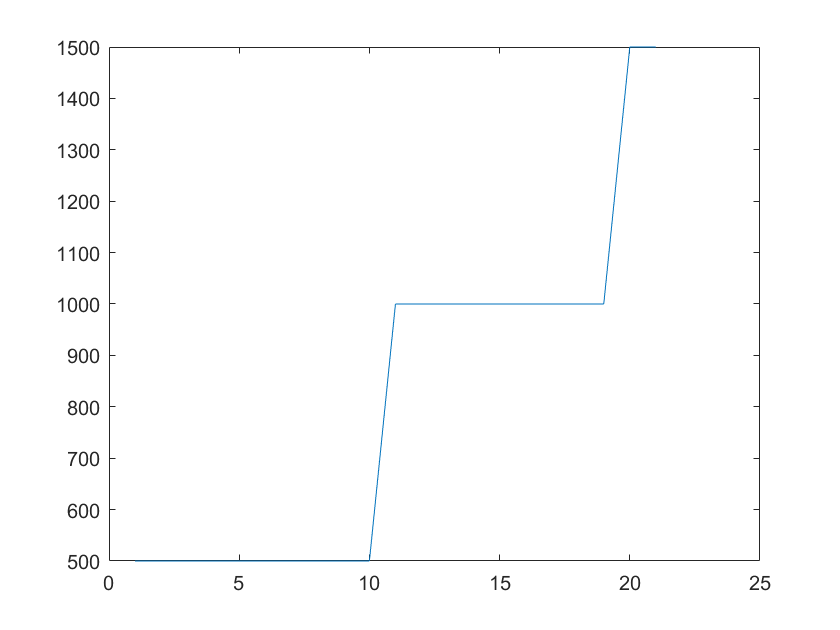

figure()
plot(traj_pt_arr)

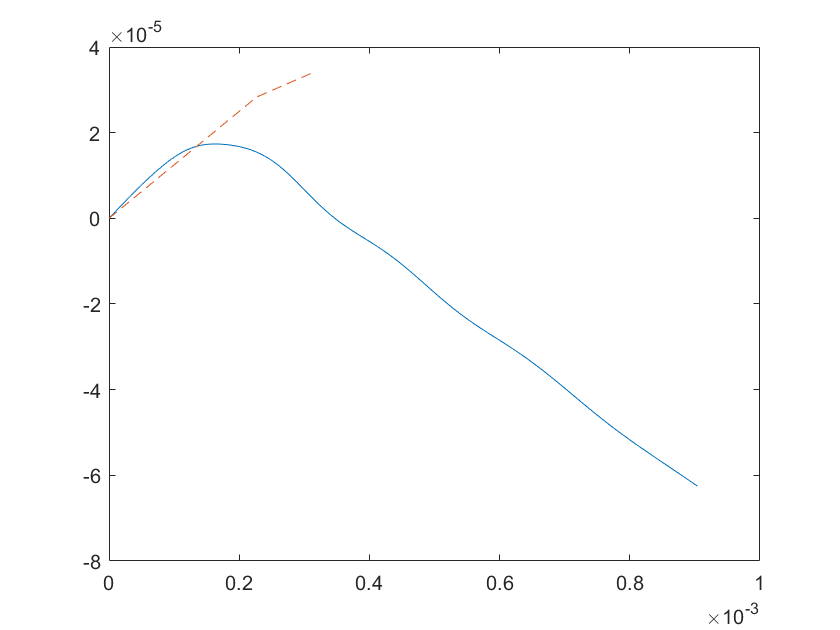

figure()
plot(PS_traj(end-200:end,3),PS_traj(end-200:end,4))
hold on
plot(PS_traj(1:5,3),PS_traj(1:5,4),'--')
hold off

size(time_arr)

ans =        24500           1


traj_pt_arr;

idx = 40;
cum_traj = [0 ;cumsum(traj_pt_arr)];
time_arr(cum_traj(idx-1)+1:cum_traj(idx),:)

ans =          0
    0.8724
    1.6732
    2.4046
    3.0676
    3.6647
    4.1986
    4.6726
    5.0905
    5.4564


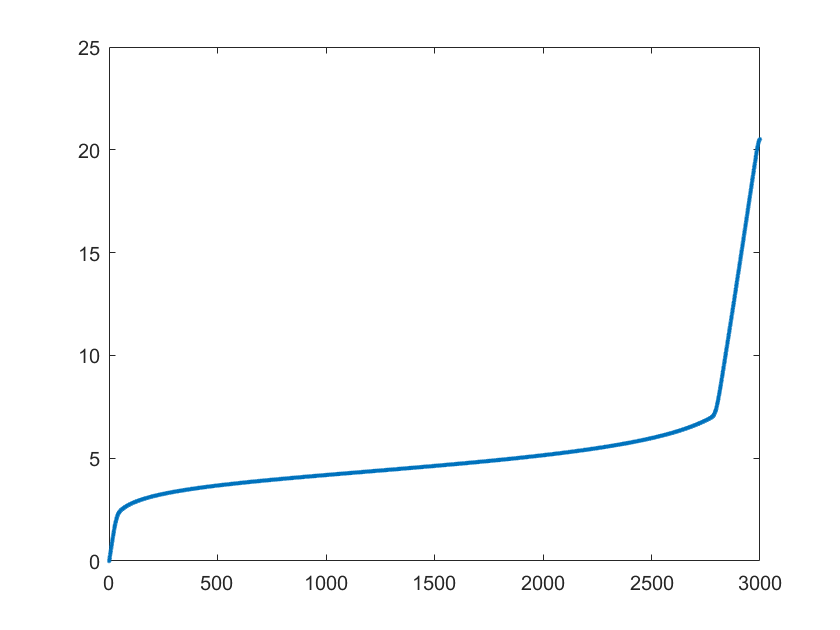

figure()
plot(t_traj,'.')

ans = 	1.0e+-3 *

    0.2214    0.0411
    0.2556    0.0455
    0.2899    0.0499
    0.3242    0.0543
    0.3585    0.0588


ans = 	1.0e+-4 *

    0.4168    0.0646
    0.3152    0.0493
    0.2114    0.0333
    0.1068    0.0170
         0         0


ans =     0.0692
    0.0692
    0.0691
    0.0691
    0.0690


ans =     0.0232
    0.0176
    0.0119
    0.0060
         0


ans = 	1.0e+-3 *

         0         0
    0.2385    0.0433
    0.2728    0.0477
    0.3071    0.0521
    0.3414    0.0565


ans = 	1.0e+-4 *

    0.4663    0.0719
    0.3660    0.0570
    0.2633    0.0413
    0.1591    0.0252
         0         0


ans =     0.0692
    0.0691
    0.0691
    0.0691
    0.0690


ans =     0.0310
    0.0259
    0.0204
    0.0148
    0.0090


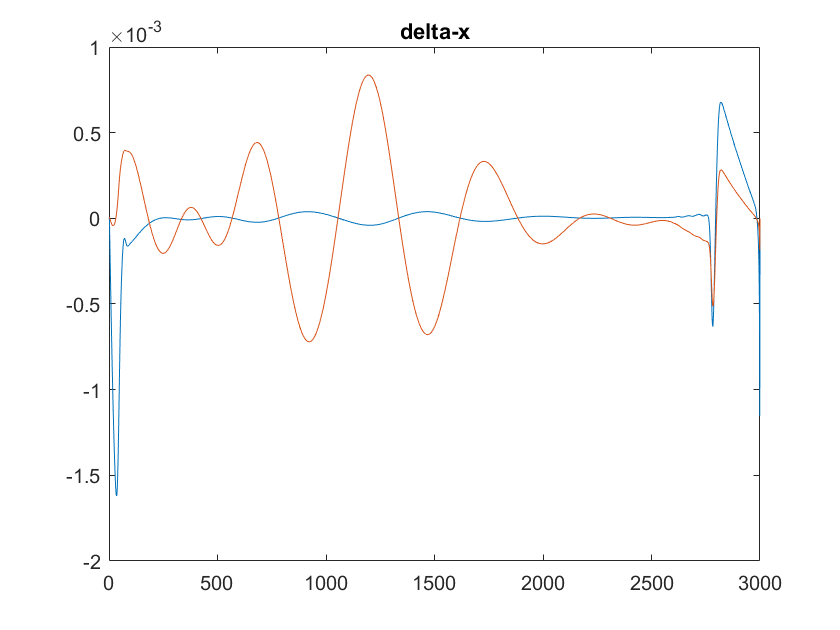

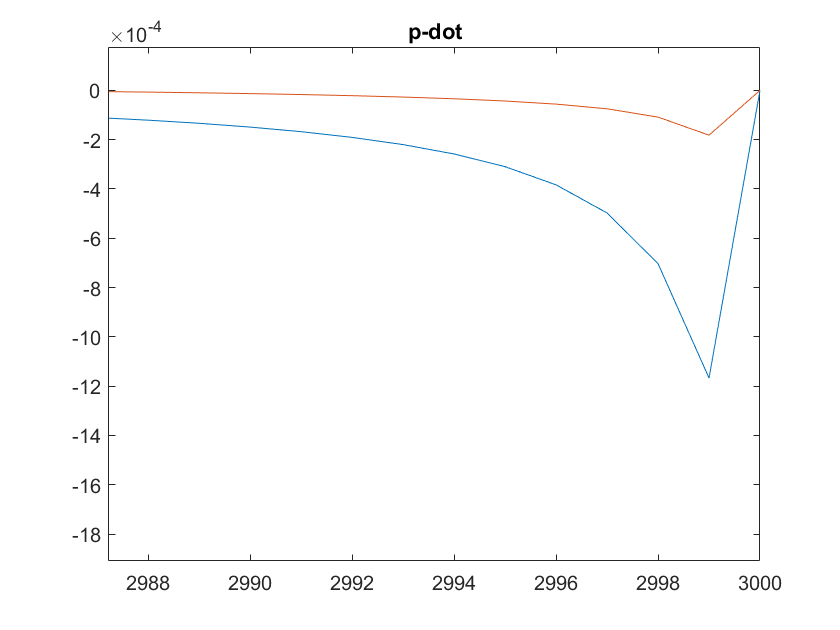

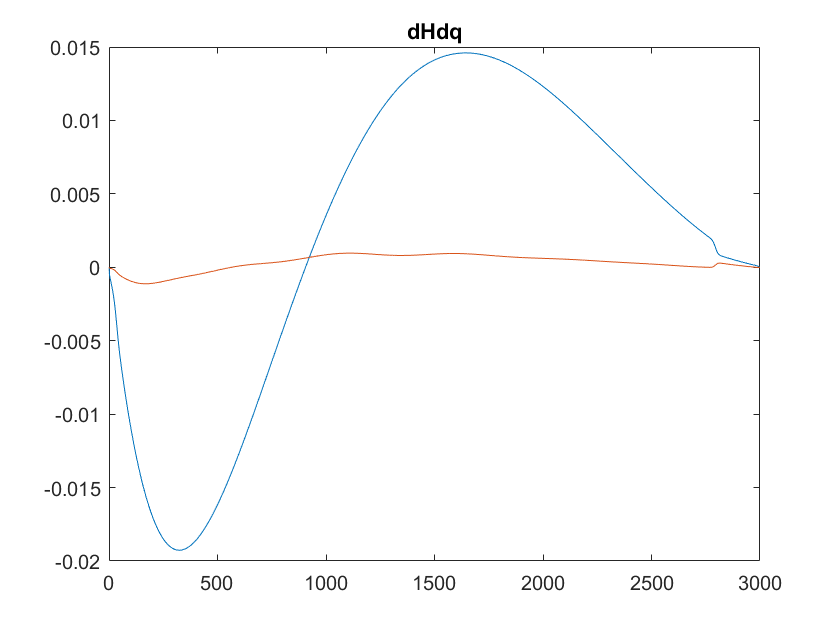

num_smooth = 45;
[PS_traj, t_traj, delta_x] = traj_2_PS_traj_func(traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,num_smooth);

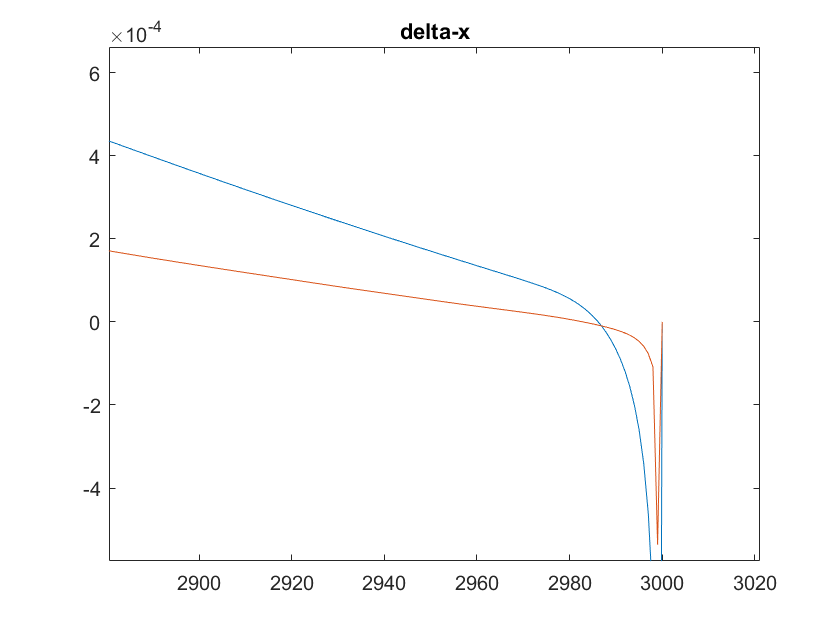

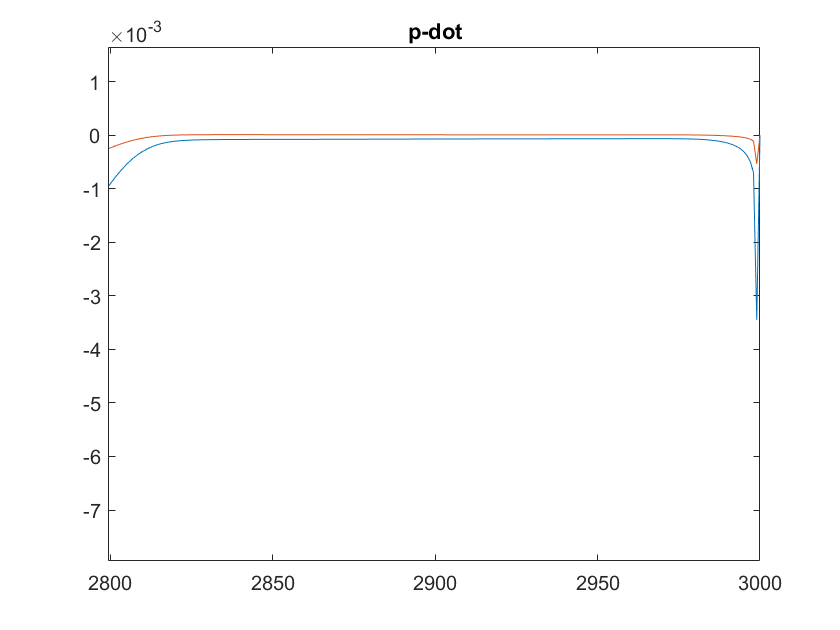

num_smooth = 45;
[PS_traj, t_traj, delta_x] = traj_2_PS_traj_func(traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,num_smooth);

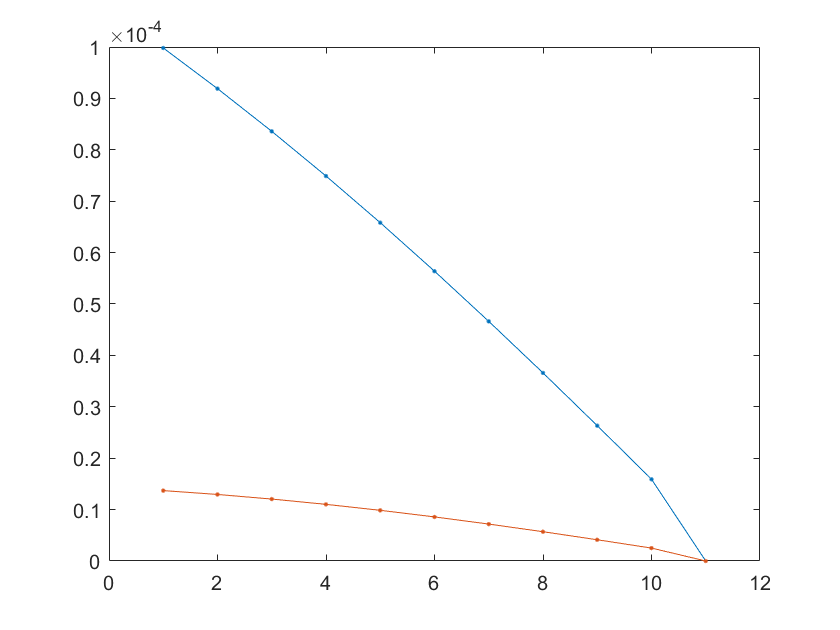

figure()
plot(PS_traj(end-10:end,3:4),'.-')

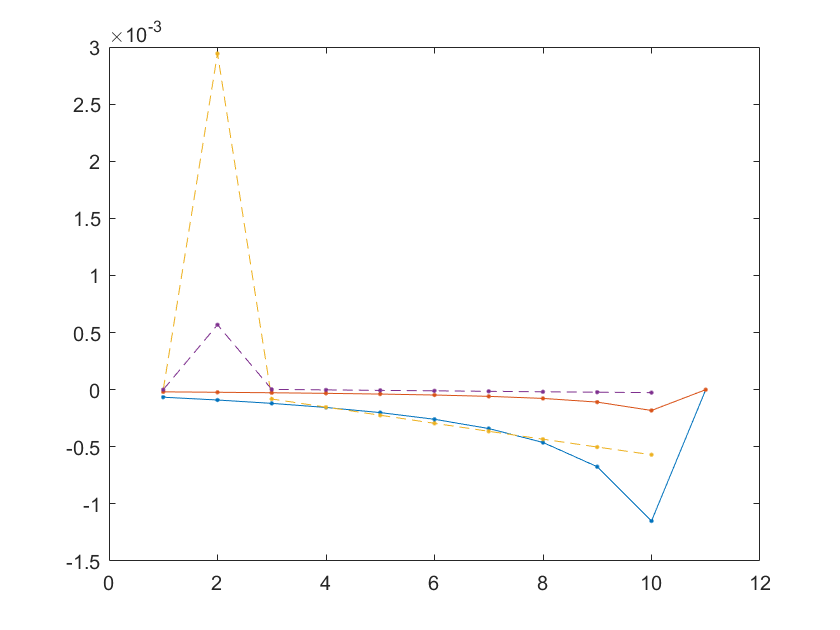

figure()
plot(delta_x(end-10:end,:),'.-')
hold on
plot(delta_x(1:10,:),'.--')
hold off

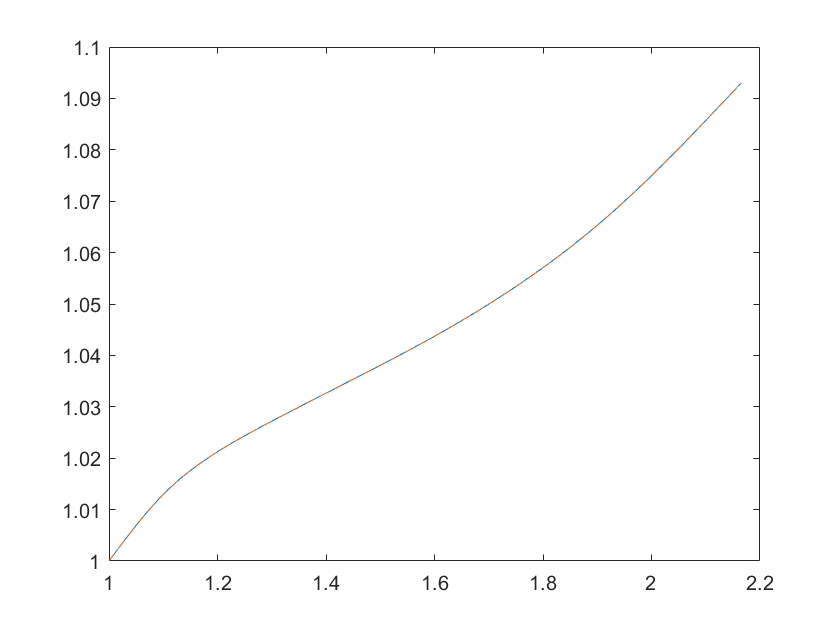

traj_pts_new = traj_pts+1000;
traj_n_s = time_uniform_filter(traj,t_traj,traj_pts_new,35);

%Plot PS_traj and save
save_plot_name = 'Plots/'+model_name+'_'+string(sad_pt)...
+'_'+string(stab_pt_choice)+'_PS_traj'+string(iter)+'.png'

save_plot_name = "Plots/Schlogl_1_2_1_2_PS_traj50.png"

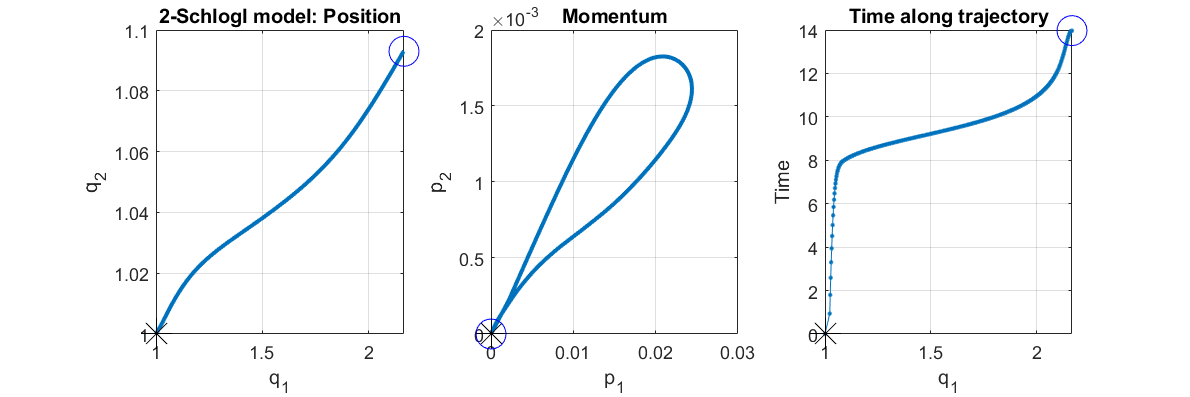

plot_PS_traj(PS_traj,t_traj,plotnam,save_plot_name,0);

%Plot delta_x and save
save_plot_name = 'Plots/'+model_name+'_'+string(sad_pt)...
+'_'+string(stab_pt_choice)+'_deltax'+string(iter)+'.png'

save_plot_name = "Plots/Schlogl_1_2_1_2_deltax14.png"

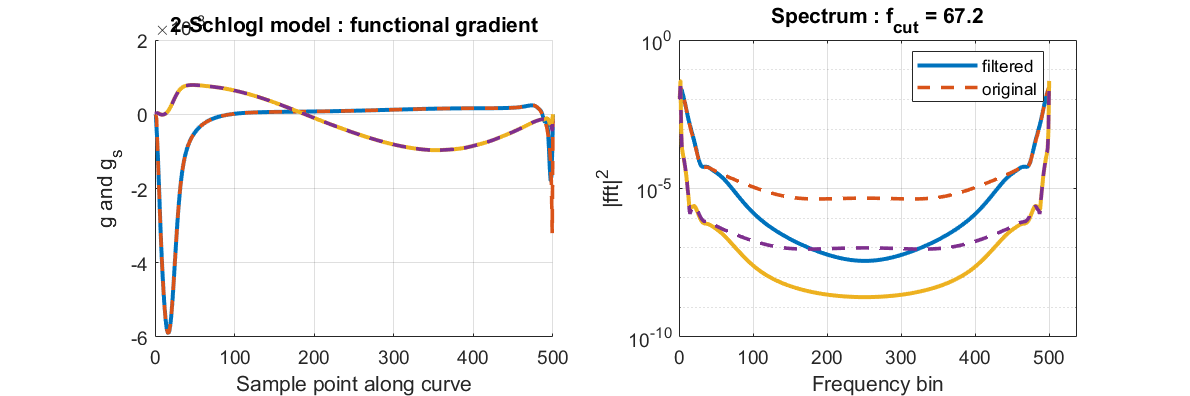

debugging_deltax_plots(delta_x,delta_x_s,f0,plotnam,save_plot_name,0);

%Plot delta_x and save
save_plot_name = 'Plots/'+model_name+'_'+string(sad_pt)...
+'_'+string(stab_pt_choice)+'_deltax'+string(iter)+'.png'

save_plot_name = "Plots/Schlogl_1_2_1_2_deltax106.png"

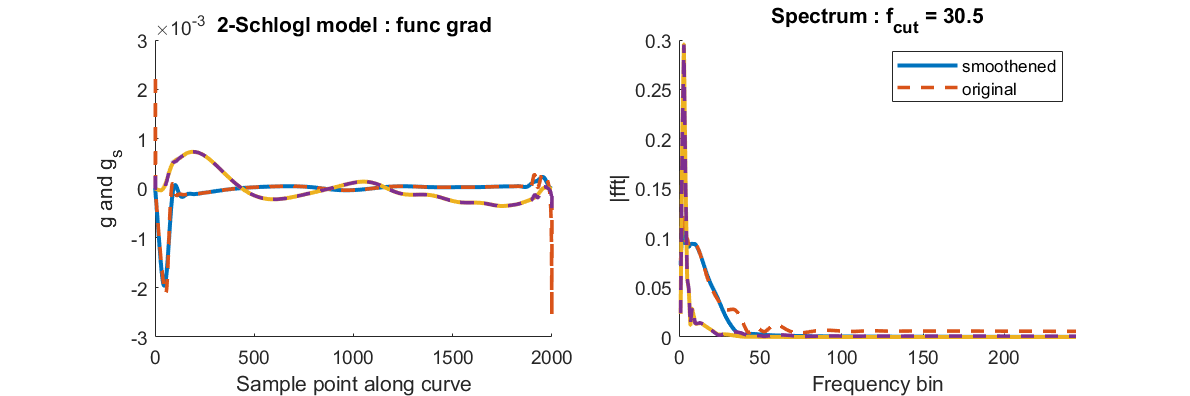

debugging_deltax_plots(delta_x,delta_x_s,f0,plotnam,save_plot_name,0);

%Plot delta_x and save
save_plot_name = 'Plots/'+model_name+'_'+string(sad_pt)...
+'_'+string(stab_pt_choice)+'_deltax'+string(iter)+'.png'

save_plot_name = "Plots/Schlogl_1_2_1_2_deltax109.png"

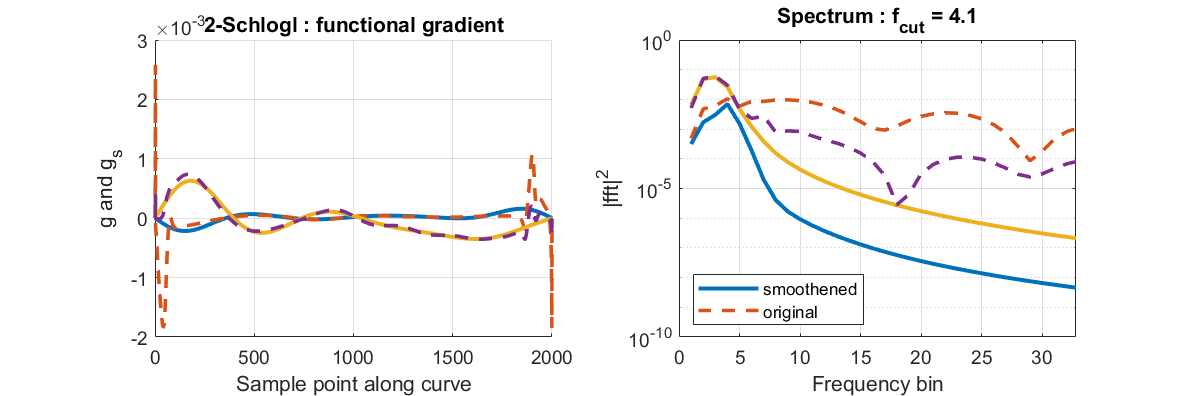

debugging_deltax_plots(delta_x,delta_x_s,f0,plotnam,save_plot_name,0);

savenam

savenam = "..\Data\Schlogl_1_2_descend_1_2straight_2000_09-Jul-2022.mat"

delta_x(3,:)

ans = 	1.0e+-3 *

   -0.0681    0.1228


[traj,len_curve_prime] = space_uniform_sampling(traj,traj_pts);


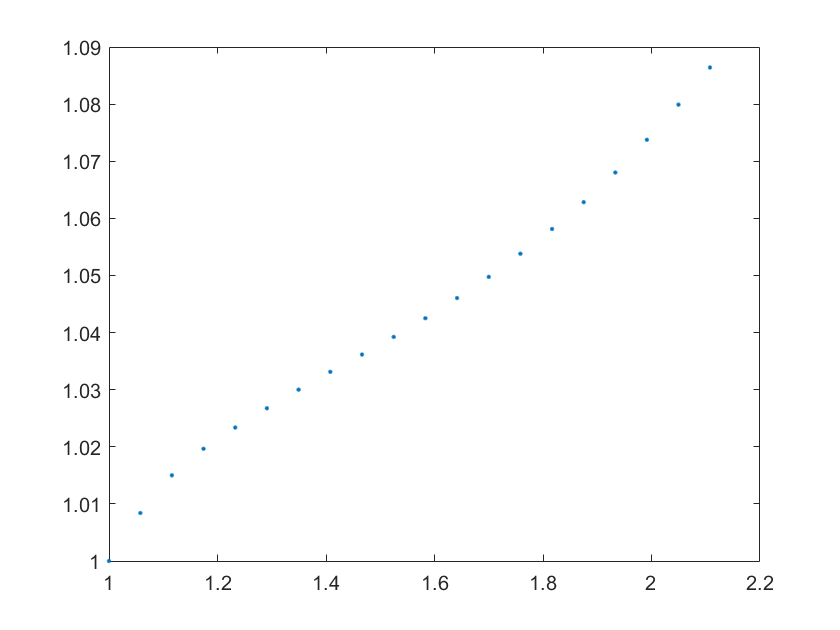

figure()
plot(traj(1:100:end,1),traj(1:100:end,2),'.')

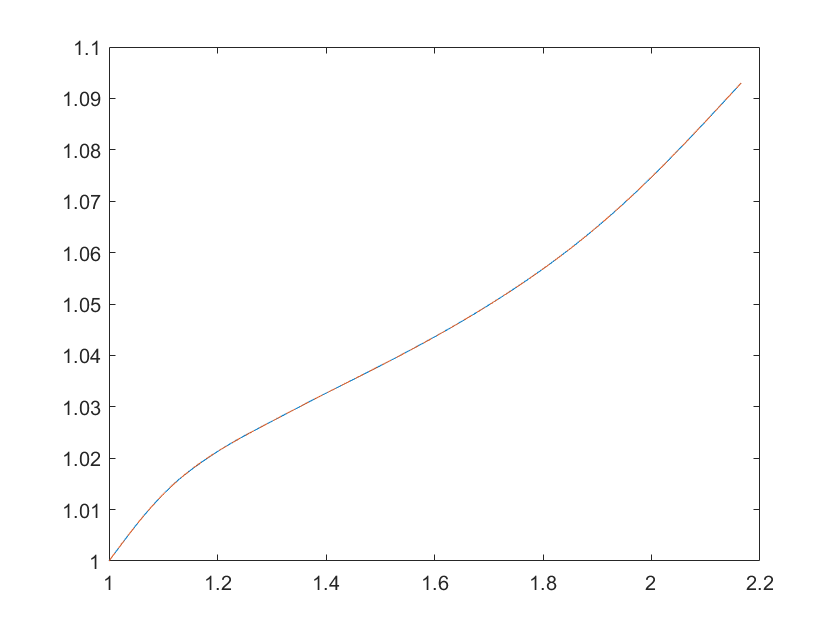

traj_pts_new = traj_pts;
traj_n_s = time_uniform_filter(traj,t_traj,traj_pts_new);
[PS_traj, t_traj, delta_x] = traj_2_PS_traj_func(traj_n_s,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,num_smooth);

figure()
plot(traj_n_s(:,1),traj_n_s(:,2))
hold on
plot(traj(:,1),traj(:,2),'--')
hold off

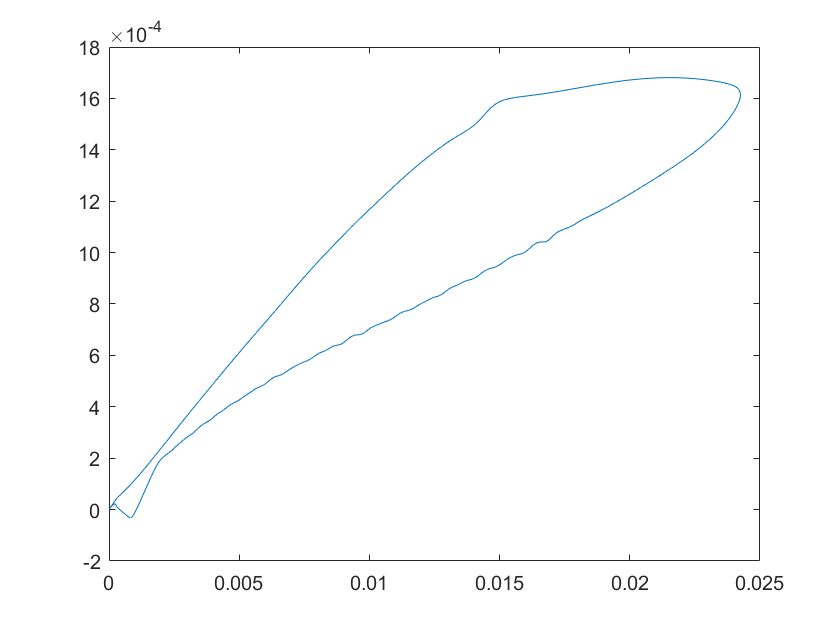

figure()
plot(PS_traj(:,3),PS_traj(:,4))  